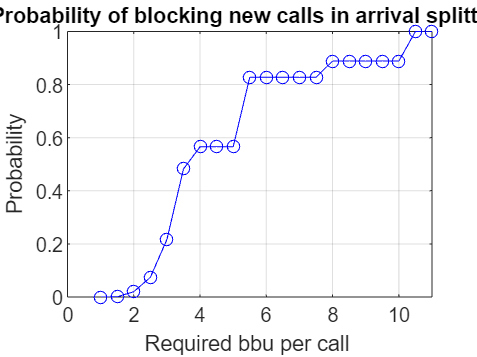

% network parameters and variables
global C1 C2 T1 T2 b;
C1 = 15; T1 = 10;
C2 = 30; T2 = 20;
b = 1; % Required bandwidth for each call
global b1 b2;


% Simulation parameters
observation_time = 21; % Simulation time in seconds
ar_new = 1; % New call arrival rate per second
dr_new = 0.5; % New call deparure rate per second
ar_han = 1; % Handoff call arrival rate per second
dr_han = 0.5; % Handoff call departure rate per second

global p_new p_han;
% Storing results in arrays for plotting

PB_values_arrival_bbu = [];
PD_values_arrival_bbu = [];
bbu_values = [];

utilization_values_arrival_bbu = [];

% Main simulation loop
for time = 1:observation_time

    b1 = b; b2 =b;

    p_new = ar_new/dr_new;
    p_han = ar_han/dr_han;
    
    % Probabilities
    [PB, PD, Utilization] = probability();

    PB_values_arrival_bbu = [PB_values_arrival_bbu, PB];
    PD_values_arrival_bbu = [PD_values_arrival_bbu, PD];
    bbu_values = [bbu_values, b];

    % Normalized Network Utilization
    utilization_values_arrival_bbu = [utilization_values_arrival_bbu, Utilization];

   % Changing parameters with time
   b = b + 0.5;
   

end

% Visualization of blocking Probability 
figure;
plot(bbu_values, PB_values_arrival_bbu, '-ob');
xlabel('Required bbu per call ');
ylabel('Probability');
title('Probability of blocking new calls in arrival splitting');
grid on;
ylim([0, 1]);

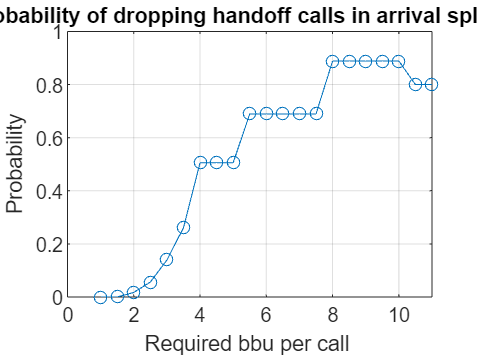

% Visualization of dropping Probability 
figure;
plot(bbu_values, PD_values_arrival_bbu, '-o');
xlabel('Required bbu per call ');
ylabel('Probability');
title('Probability of dropping handoff calls in arrival splitting');
grid on;
ylim([0, 1]);

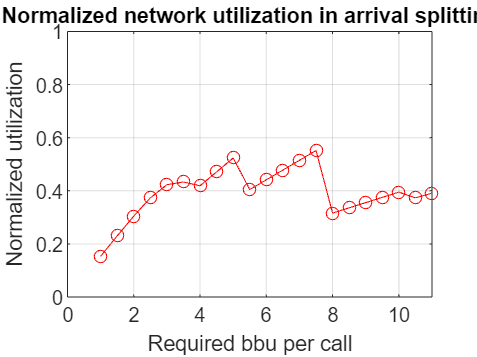


% Normalised network utilization
figure;
plot(bbu_values, utilization_values_arrival_bbu, '-or');
xlabel('Required bbu per call');
ylabel('Normalized utilization');
title('Normalized network utilization in arrival splitting');
grid on; 
ylim([0, 1]);

function [PB, PD, Utilization] = probability()
global C1 C2 T1 T2 b1 b2 p_new p_han;
SB =0; SD =0; G =0;
U = 0; 

for m2=0:T2/b2
    for n2=0:C2/b2
                m1 = round(C1/C2)*m2; % Assigning calls depending on ratio of capacities
                n1 = round(C1/C2)*n2;
                if (((b1*(m1+n1)<=C1) && (b1*m1<=T1))) && (((b2*(m2+n2)<=C2) && (b2*m2<=T2)))
                    P= (((p_new^m1)*(p_han^n1))/(factorial(m1) * factorial(n1))) * (((p_new^m2)*(p_han^n2))/(factorial(m2) * factorial(n2)));
                    G = G + P;
                    %Sum of the probabilities for blocking states
                    if ((b1+ (b1*(m1+n1)) > C1) || ((b1+ (b1*m1)) > T1)) || ((b2+ (b2*(m2+n2)) > C2) || ((b2+ (b2*m2)) > T2))
                    SB=SB+P;
                    end
                    %Sum of the probabilities for dropping states
                    if (b1+ (b1*(m1+n1)) > C1) || (b2+ (b2*(m2+n2)) > C2)
                    SD=SD+P;
                    end
                    % average Utilization
                    Us = (m1+n1)*b1 + (m2+n2)*b2;
                    U = U + (Us*P);

                    states=[(m1),(n1),(m2),(n2)];
        end
    end
end
PB = SB/G;
PD = SD/G;
Utilization = (U/G)/(C1+C2);

end


